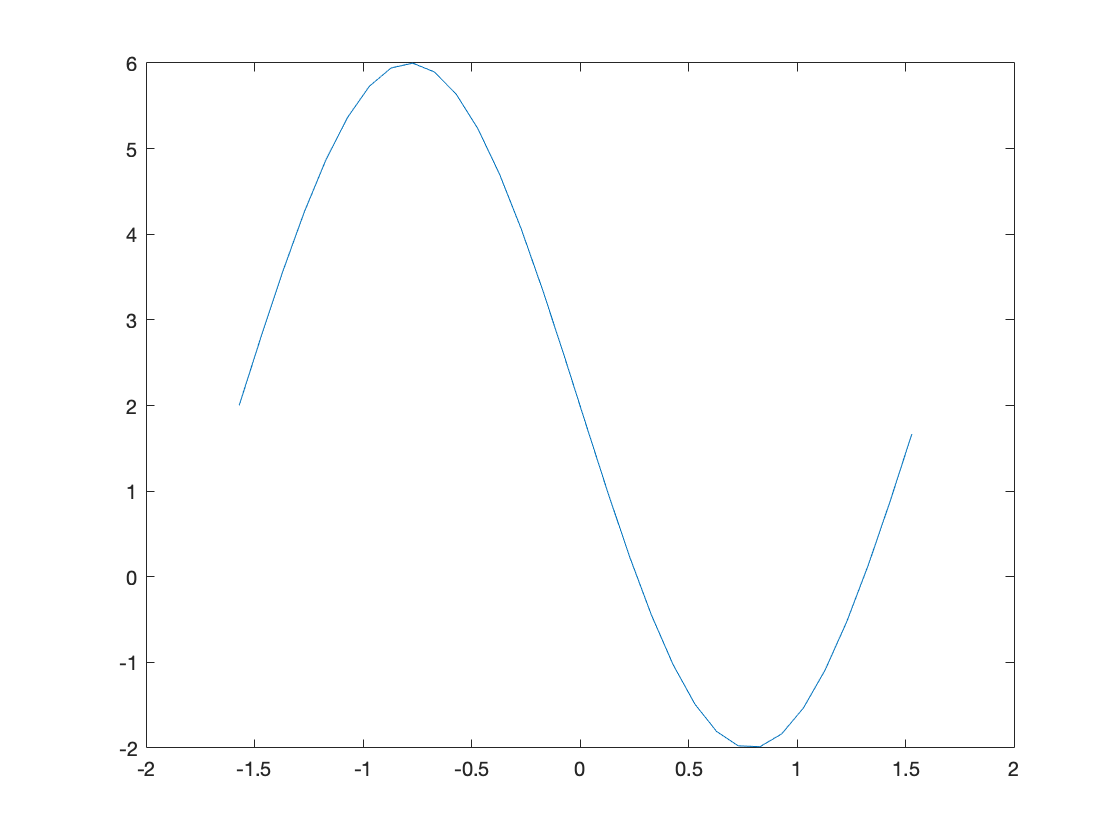

f = @(x) sin(2*x) + (x).^2;
fp = @(x) 2*cos(2*x) +2*x;
fpp = @(x) -4*sin(2*x)+2;

a = -pi/2;
b = pi/2;
err=1e-4;


% c
figure(1)
plot(a:0.1:b,fpp([a:0.1:b]))


X =ceil( sqrt( (b-a)^3/12 * err/err) )

X = 2

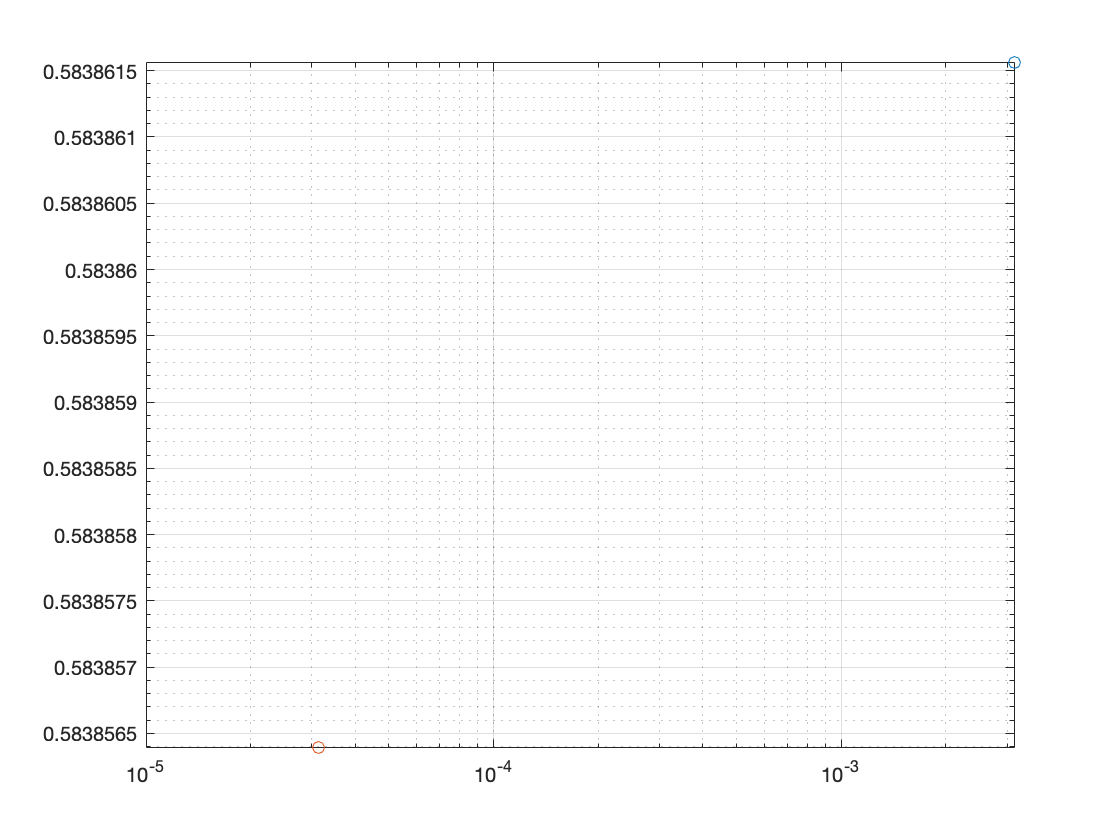


Exact = 2/3*pi^3/2^3;  %the exact value of the integral 
I1 = composite_trapezoid(f,a,b,n(1,1));
I2 = composite_trapezoid(f,a,b,n(1,2)); %to complete value

Err1 = abs(abs(X)-I1);
Err2 = abs(abs(X)-I2);
%h = (b-a)/n;
h1 = (b-a)/n(1,1);
h2 = (b-a)/n(1,2);

%loglog is a plot of error verses the number of points for both methods on the same plot.
loglog(h1,Err1,'o',h2,Err2,'o');
grid on;

sprintf('The order of the method is %g',a)

ans = 'The order of the method is -1.5708'


%function that computes \int_a^b f(x) dx using composite Trapezoid rule
%INPUTS:
%function f
%bounds of interval [a,b]
%n number of subintervals
%OUTPUT:
%I the numerical integration

%creation of the nodes and mesh size

function I = composite_trapezoid(f,a,b,n)
    h = (b-a)/n;
    x = a:h:b; %creating a vector of the values
    y= 0;
    for i = 1:n
        y = y + ((f(x(1,i))+f(x(1,i+1))).*h)./2;
    end
    I = y;
end